## Experimento 3 - MP3 Player (Parte 2)

#### Bruno Hashimoto - 10715628

#### Guilherme Fernandes - 10297272

clear;
clc;

addpath(".", "functions/", "data/");
load("h0_QMF.mat"); % filtro passa-baixas h0

### 2.a) Análise da resposta em freq. do filtro QMF com dois canais

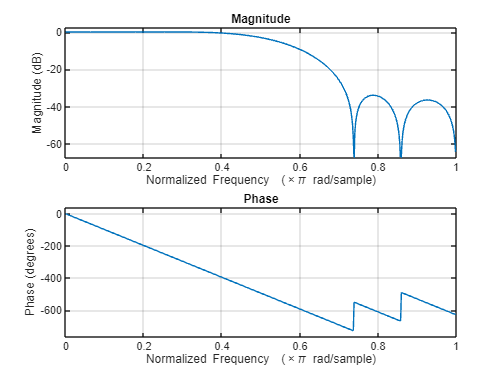

h0_order = length(h0)-1;
% obtencao do filtro passa-altas a partir de h0
h1 = real(h0 .* exp(pi*(0:h0_order)*i));
g0 = 2*h0;
g1 = -2*h1;

freqz(h0, 1);

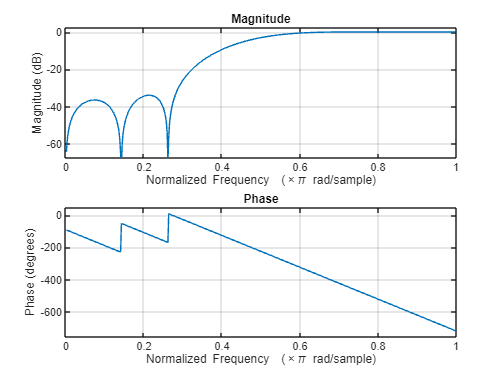

freqz(h1, 1);

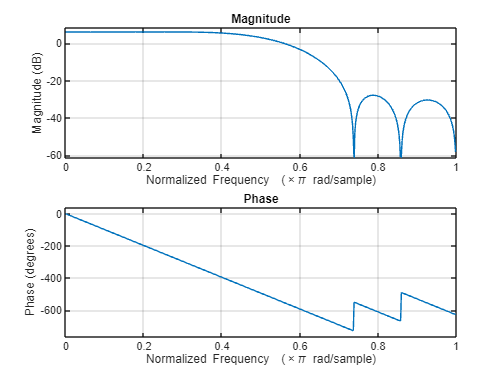

freqz(g0, 1);

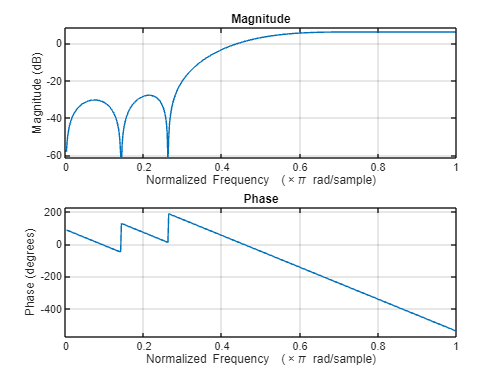

freqz(g1, 1);

Em comparação com os filtros utilizados no exercício 1, tem-se para esse caso também dois filtros FIR passa-baixas e passa-altas com a diferença que o filtro disponibilizado é de uma ordem muito menor que a do exercício anterior, de ordem 441 para 11.

### 2.b) Chirp com filtro QMF com dois canais

Inicialmente, definindo o mesmo sinal chirp.

t_inicial = 0;
t_final = 4;
f_final = 4000;
f_a = 8000;

% funcao gera chirp implementada para utilizacao 
% nos proximos exercicios, disponivel na pasta 'functions'
[x,n] = gera_chirp(t_inicial, t_final, f_final, f_a);

Reconstruindo o sinal chirp com o filtro QMF com dois canais.

% Análise-Síntese filtro passa-baixas (h0, g0)
% Análise
v0 = filter(h0, 1, x);
v0 = sub_amostragem(v0, 2);
% Síntese
y0 = sobre_amostragem(v0, 2);
y0 = filter(g0, 1, y0);

% Análise-Síntese filtro passa-altas (h1, g1)
% Análise
v1 = filter(h1, 1, x);
v1 = sub_amostragem(v1, 2);
% Síntese
y1 = sobre_amostragem(v1, 2);
y1 = filter(g1, 1, y1);


Da mesma forma que anteriormente, a combinação dos dois canais reconstrói o sinal. Porém precisa-se corrigir o atraso gerado pelos filtros. O atraso de cada filtro é $\frac{N-1}{2}$ , como o sinal em cada canal é filtrado duas vezes o atraso é de $N-1$, que é a ordem do filtro.

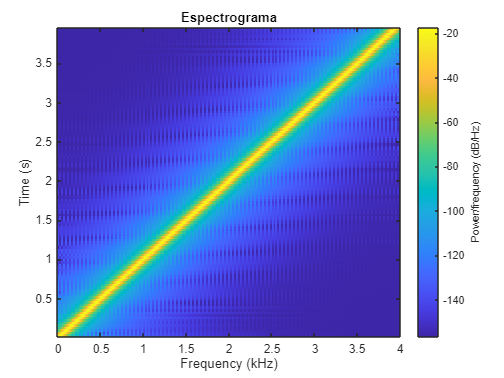

% precisa tirar o atraso de y0 e y1
y = y0(h0_order+1:end) + y1(h0_order+1:end);

figure;
spectrogram(y, hanning(512), 256, 1024, f_a);
title('Espectrograma');